# Genetic Algorithm

Michael Kmak

    - from code by Dr. David Mueller

Computational Intelligence

### Problem Statement:

Use a genetic algorithm to find the global optimum of the following objective function:


$$f(x,y)=\exp\left( \frac{-\left[ (x-3)^2+(y-3)^2\right]}{5} \right) +
\exp\left( \frac{-\left[ x^2+(y+3)^2\right]}{5} \right) + 
0.2\left[ \cos\left(\frac{x\pi}{2}\right) + \cos\left(\frac{y\pi}{2}\right)\right] +
0.5$$


objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

Mathematically we know this function has a maximum height of 1.6903 in the range of -5 to 5 for x and y.

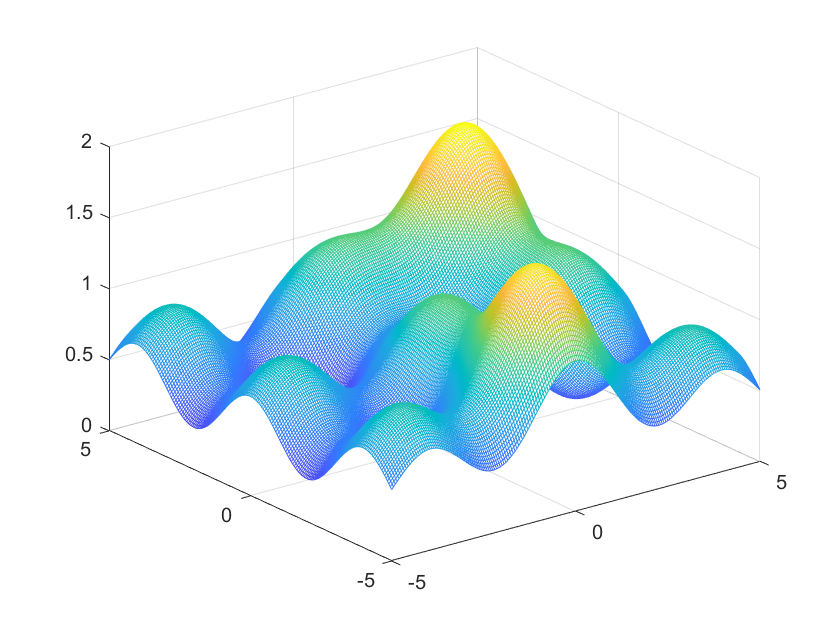

[x,y]=meshgrid(-5:0.05:5);
mesh(x,y,objf(x,y));

### Methods:

- Representation: Binary

- Selection: Proportional (Roulette Wheel) Selection

- Mating/Variation: Single Point Binary Crossover, Uniform Crossover

### Initialize Parameters

For a genetic algorithm, the important parameters are population size, number of generations to execute, fraction of population seleected for mating, the data representation, and the range of data. Also included is the number of trials to run.

clearvars
objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;
% ***** User Changable Variables ***** %
trials = 200;           %how many trials to run
pop = 40;               %population size
gen = 200;              %number of generations
pcntsel = 0.5;          %fraction of candidated selected for next generation
np = 1.5;
nm = 2 - np;

precision = 8;          %precision of real number represenation (ex. 8 -> 8-bit represenation)
range = [-5 5; -5 5];   %bounds for input variables
uniform = 1;            %crossover algorithm
selmethod = 'roulette'; %'elitist', 'roulette', 'tournament', ranking'


% ***** Calculations ***** %
mu = round(pcntsel*pop);    %number of parents selected
lambda = pop - mu;          %number of new candidates in each generation (children)

best = zeros(trials, gen, 5); % tracking the best candidate in each trial, per generation, per method

### Generate Initial Population

Generally, the initial population is generated randomly within specified ranges. 

% candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
% candidate.biny = rand(pop,precision)>0.5;

### Genetic Algorithm

methods = ["elitist-plus","elitist-comma", "roulette", "tournament", "ranking"];
for m = 1:5
    selmethod = methods(m);
    for t = 1:trials
        % initialize the new trial
        candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
        candidate.biny = rand(pop,precision)>0.5;
        
        for i = 1:gen
            
            % ********* Convert Representation ****** %
            candidate.x = (range(1,1)-range(1,2))*(bi2de(candidate.binx)/(2^precision-1))+range(1,2);
            candidate.y = (range(2,1)-range(2,2))*(bi2de(candidate.biny)/(2^precision-1))+range(2,2);
            % *************************************** %
            
            % ********* Get Fitness ***************** %
            candidate.fit = objf(candidate.x,candidate.y);
            % record best of the generation
            [~,bi] = max(candidate.fit);
            best(t,i,m) = candidate.fit(bi);
            % *************************************** %
            
            % ********* Select Parents  ************* %
            parents = zeros(1,mu);
            switch selmethod
                case 'elitist-plus'
                    for k = 1:mu
                        [~,b] = max(candidate.fit);
                        candidate.fit(b) = 0;
                        parents(k) = b;
                    end
                case 'elitist-comma'
                    for k = 1:mu
                        [~,b] = max(candidate.fit);
                        candidate.fit(b) = 0;
                        parents(k) = b;
                    end
                case 'roulette'
                    fitsum = sum(candidate.fit);
                    candidate.p = candidate.fit./fitsum;
                    p = discreteinvrnd(candidate.p);
                    for k = 1:mu
                        while ismember(p, parents)
                            p = discreteinvrnd(candidate.p);
                        end
                        parents(k) = p;
                    end
                case 'tournament'
                    bracket = randperm(pop);
                    for k = 1:2:pop
                        if candidate.fit(bracket(k)) > candidate.fit(bracket(k+1))
                            parents(ceil(k/2)) = bracket(k);
                        else
                            parents(ceil(k/2)) = bracket(k+1);
                        end
                    end
                case 'ranking'
                    % rank
                    ranking = zeros(1,pop);
                    for k = 1:pop
                        [~,b] = max(candidate.fit);
                        candidate.fit(b) = 0;
                        ranking(k) = b;
                    end
                    term = (np-nm)/(pop-1);
                    for k = 1:pop
                        candidate.p(ranking(k)) = (np-term*(k-1))/pop;
                    end
                    p = discreteinvrnd(candidate.p);
                    for k = 1:mu
                        while ismember(p, parents)
                            p = discreteinvrnd(candidate.p);
                        end
                        parents(k) = p;
                    end
            end
            children = setdiff(1:pop, parents);
            % *************************************** %
            
            % ********* Create Offspring ************ %
            if ~uniform
                % 1-point
                for k = 1:2:lambda
                    pt = randi(precision-1); % random point to split chromosomes
                    % first child
                    candidate.binx(children(k),:) = horzcat(...
                        candidate.binx(parents(k),1:pt), ...
                        candidate.binx(parents(k+1),pt+1:precision));
                    candidate.biny(children(k),:) = horzcat(...
                        candidate.biny(parents(k),1:pt), ...
                        candidate.biny(parents(k+1),pt+1:precision));
                    % second child (inverse)
                    candidate.binx(children(k+1),:) = horzcat(...
                        candidate.binx(parents(k+1),1:pt), ...
                        candidate.binx(parents(k),pt+1:precision));
                    candidate.biny(children(k+1),:) = horzcat(...
                        candidate.biny(parents(k+1),1:pt), ...
                        candidate.biny(parents(k),pt+1:precision));
                end
            else
                % uniform crossover
                % generates a random bitmap in which each bit is uniformly random
                % and muxes the parents according to it.
                map = rand(lambda,precision)>0.5;
                for k = 1:2:lambda
                    % first child
                    candidate.binx(children(k),:) = mux(...
                        candidate.binx(parents(k),:)...
                        , candidate.binx(parents(k+1),:), map(k,:));
                    candidate.biny(children(k),:) = mux(...
                        candidate.biny(parents(k),:)...
                        , candidate.biny(parents(k+1),:), map(k,:));
                    % second child (inverse)
                    candidate.binx(children(k+1),:) = mux(...
                        candidate.binx(parents(k+1),:)...
                        , candidate.binx(parents(k),:), map(k,:));
                    candidate.biny(children(k+1),:) = mux(...
                        candidate.biny(parents(k+1),:)...
                        , candidate.biny(parents(k),:), map(k,:));
                end
            end
            % *************************************** %
            
            % fill the parents for comma elitist
            if selmethod == 'elitist-comma'
                for k=1:mu
                    candidate.binx(parents(k),:) = rand(1, precision)>0.5;
                    candidate.biny(parents(k),:) = rand(1, precision)>0.5;
                end
            end
        end
    end
end

### Results and Conclusions

The Tournament and Elitist (Comma) selection algorithms performed the best. They quickly found a good solution and stayed there. The comma elitist method actually continued to improve thanks to the addition of random mutations. The plus elitist also suffered from convergence, but the solution was better than the last two algotirhms. These were also able to quickly find an optimal solution but declined just as quickly. Roulette Wheel especially suffers from this. None of the algorithms find the precisely optimal solution of 1.69, but Tournament and Elitist get noticeably closer than Roulette, and they do so more stably. Each of the four algorithms that don't add random mutations would greatly benefit from this addition. As for convergence, Elitist and Tournament converge extremely quickly. Tournament converges both at a higher mean and a tighter distribution. Linear ranking converges fairly quickly but very scattered and at a poor mean.

#### Elitist (Plus) Selection:

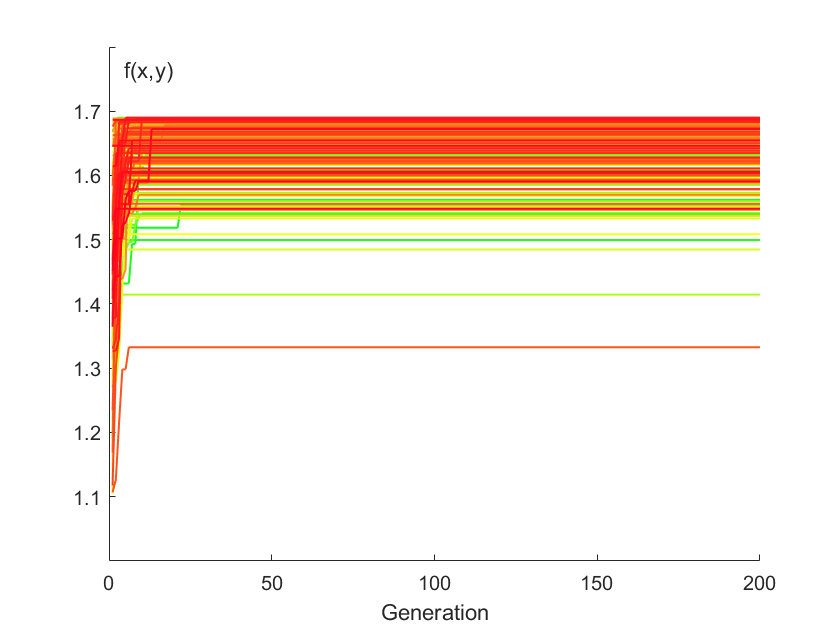

plot_best(best(:,:,1));

#### Elitist (Comma) Selection:

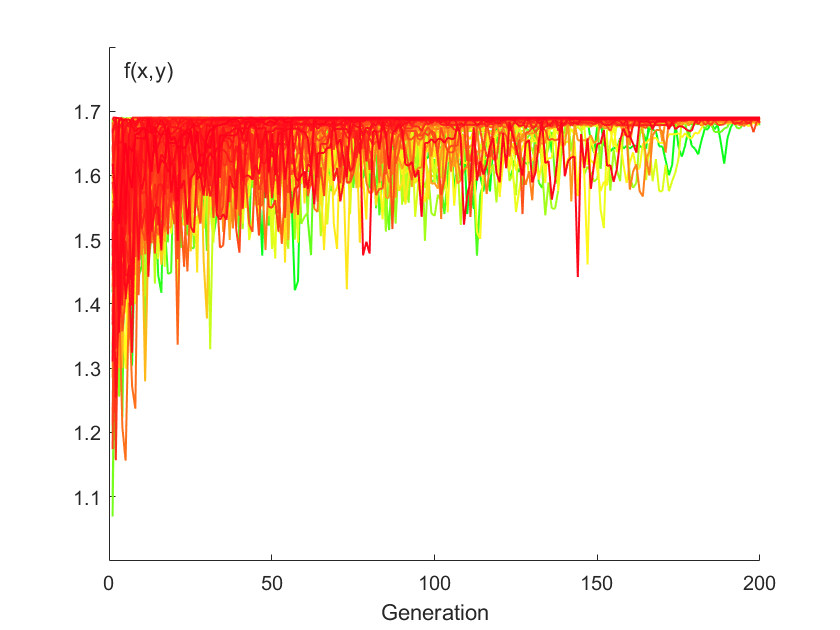

plot_best(best(:,:,2));

#### Roulette Wheel Selection:

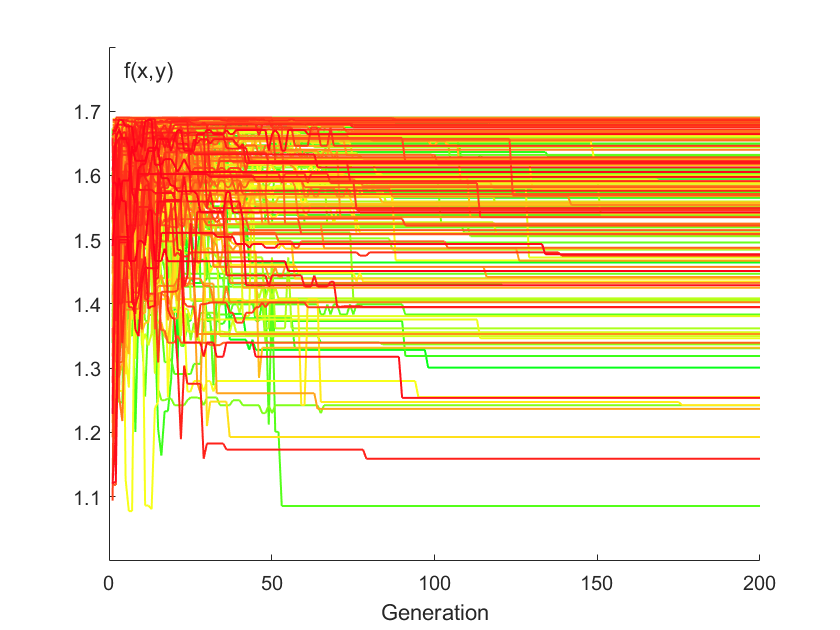

plot_best(best(:,:,3));

#### Tournament Selection:

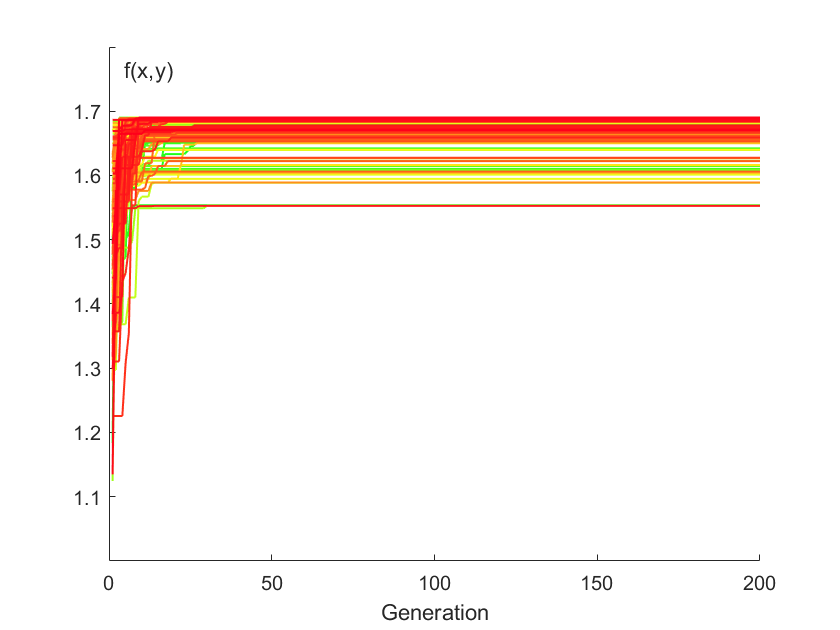

plot_best(best(:,:,4));

#### Linear Ranking Selection:

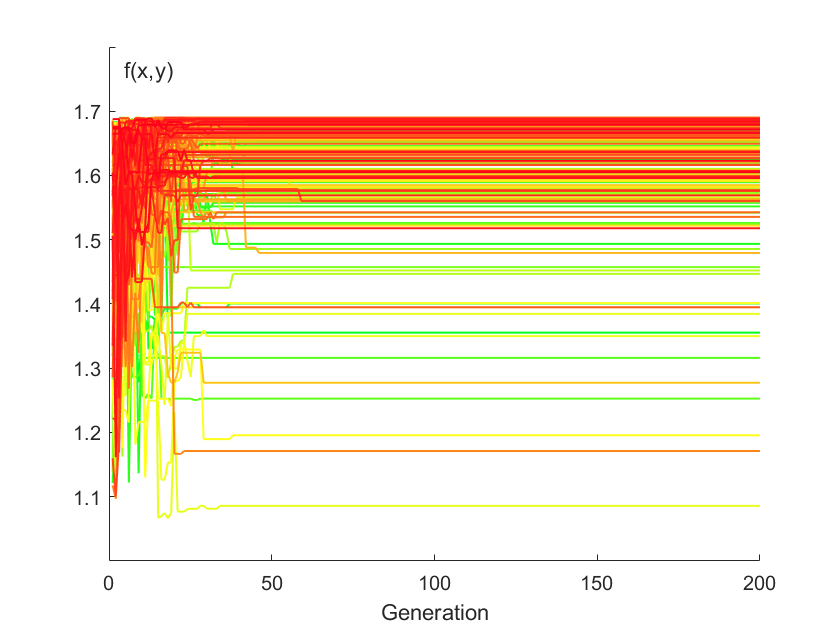

plot_best(best(:,:,5));

#### Average of Bests

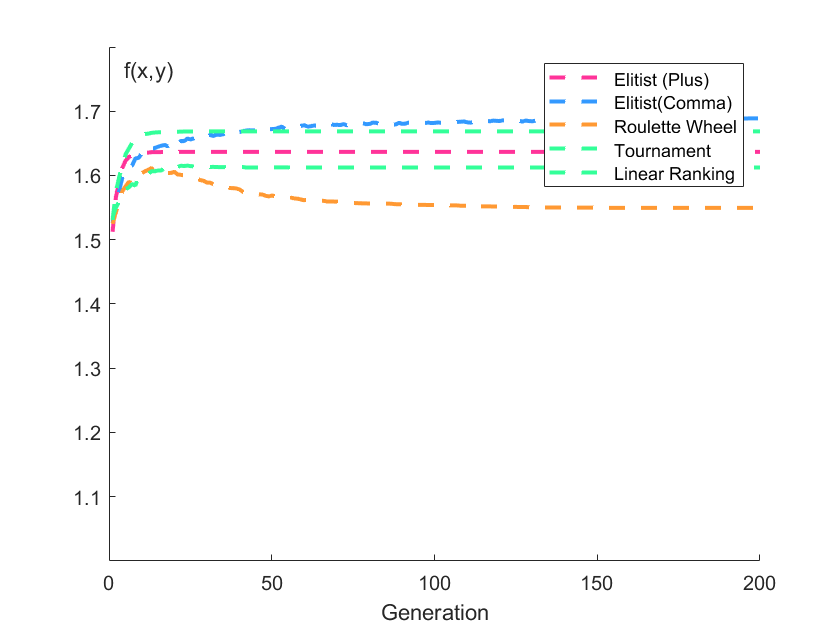

plot_bavg(best);

### Helper Functions

Logical muxer:

function Y = mux(A, B, S)
    Y = (~S & A) | (S & B);
end

Plot the recorded best candidates:

function plot_best(best)
    figure();
    hold on;
    axis([-0.1 width(best) 1 1.8]);
    xlabel('Generation');
    ylabel('f(x,y)');
    ax = gca;
    ax.XAxisLocation='origin';
    ax.YAxisLocation='origin';
    figy = 1:width(best);
    tmax = height(best);
    for t = 1:tmax
        plot(figy, best(t,:), 'Color',[min(t/(0.5*tmax),1) min((tmax-t)/(0.5*tmax),1) .1], 'LineStyle', '-','LineWidth',1);
    end
end

Plot the average of bests for each generation

function plot_bavg(best)
    figure();
    hold on;
    axis([-0.1 width(best) 1 1.8]);
    xlabel('Generation');
    ylabel('f(x,y)');
    ax = gca;
    ax.XAxisLocation='origin';
    ax.YAxisLocation='origin';
    figy = 1:width(best);
    bavg = zeros(width(best),4);
    for i=1:size(best,2)
        for k = 1:size(best,3)
            bavg(i,k) = mean(best(:,i,k));
        end
    end
    plot(figy, bavg(:,1), 'Color',[1 .2 .6], 'LineStyle', '--','LineWidth',2);
    plot(figy, bavg(:,2), 'Color',[.2 .6 1], 'LineStyle', '--','LineWidth',2);
    plot(figy, bavg(:,3), 'Color',[1 .6 .2], 'LineStyle', '--','LineWidth',2);
    plot(figy, bavg(:,4), 'Color',[.2 1 .6], 'LineStyle', '--','LineWidth',2);
    plot(figy, bavg(:,5), 'Color',[.2 1 .6], 'LineStyle', '--','LineWidth',2);
    legend('Elitist (Plus)', 'Elitist(Comma)', 'Roulette Wheel', 'Tournament', 'Linear Ranking');
end

Generates a random number according to PMF p. Adapted from [https://www.mathworks.com/help/stats/generating-random-data.html](https://www.mathworks.com/help/stats/generating-random-data.html)

function X = discreteinvrnd(p)
    u = rand;
    I = find(u < cumsum(p));
    X = min(I);
end